# Práctica #01: Médición de Resistencia

***Autor(a): Francisco Javier Ramírez Arias, Profesor-Investigador de Tiempo Completo, Universidad Autónoma de Baja California, (FCITEC-Valle de las Palmas).***

## Resumen

La **Práctica 01: Medición de Resistencia** tiene como objetivo que el estudiante aprenda a utilizar el **multímetro digital** para **medir resistencias**, comprendiendo su **funcionamiento**, la correcta **selección de rangos** y evitando **errores comunes**. Se identifican los **valores nominales** de **10 resistencias** mediante el **código de colores**, se **registran** en **MATLAB** y se **comparan** con los **valores reales medidos**. Además, se calcula el **porcentaje de error** para evaluar la **precisión** y determinar si las **mediciones** están dentro del **rango de tolerancia**. Finalmente, se **analizan los resultados obtenidos**, desarrollando **habilidades** para **interpretar datos**, **detectar discrepancias** y aplicar criterios de **exactitud** y **confiabilidad** en las **mediciones**.

## Objetivos de Aprendizaje

En esta práctica los estudiantes aprenderán a utilizar el multímetro digital para la medición de resistencias, comprendiendo su funcionamiento básico, la correcta selección de rangos y la importancia de evitar errores comunes. Se busca que comparen los valores obtenidos con los nominales, apliquen correcciones necesarias, analicen la incertidumbre de sus mediciones y desarrollen habilidades para registrar, organizar e interpretar los resultados de forma crítica y confiable.

### **Conceptos, contenido y habilidades a desarrollar**

- Funcionamiento y uso del multímetro digital.

- Selección de rangos, resolución y tolerancia del instrumento.

- Técnicas adecuadas de medición de resistencias.

- Corrección de errores en la medición.

- Comparación entre valores medidos y valores nominales (código de colores).

- Análisis de incertidumbre (errores sistemáticos y aleatorios).

- Registro, organización y representación de datos.

- Interpretación crítica de resultados: precisión, exactitud y confiabilidad.

## Introducción

La medición de resistencia constituye una actividad fundamental dentro del laboratorio de mediciones eléctricas y electrónicas, ya que permite conocer con precisión el valor real de los componentes y compararlo con el valor nominal establecido por el fabricante. Esta verificación es indispensable para asegurar el correcto funcionamiento de circuitos y sistemas electrónicos, además de servir como punto de partida en la detección de fallas y en el control de calidad de materiales.

El multímetro digital es el instrumento más utilizado para este tipo de mediciones debido a su facilidad de uso, versatilidad y exactitud. Sin embargo, obtener resultados confiables requiere una correcta selección del rango de trabajo, el cuidado en la conexión de las puntas de prueba y la identificación de posibles fuentes de error, como contactos deficientes, resistencia de los cables o variaciones por temperatura.

A través de esta práctica, los estudiantes no solo se familiarizarán con el uso adecuado del multímetro digital, sino que también desarrollarán competencias para registrar, analizar y comparar sus resultados, reforzando así la importancia de la precisión y la interpretación crítica en la experimentación.

### Código de Colores de las Resistencias

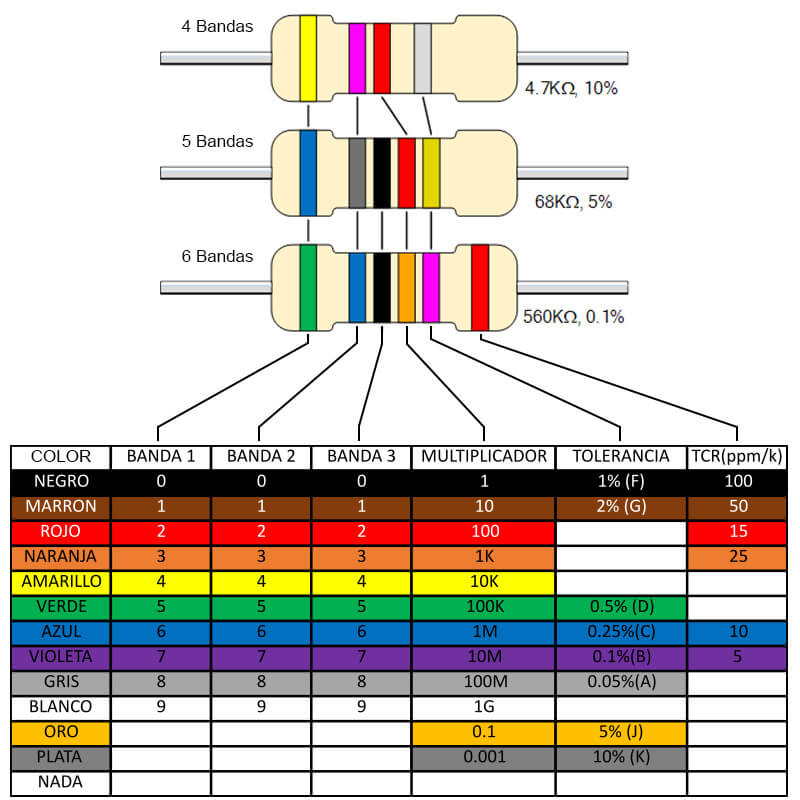

### Ejemplos:

***Ejemplo 01:*** Tenemos una resistencia con las siguientes **bandas de colores**:

- **Rojo**

- **Violeta**

- **Amarillo**

- **Oro**

**Paso 1: Identificar el valor de cada color**

- **Rojo = 2**

- **Violeta = 7**

- **Amarillo = ×10⁴** (multiplicador)

- **Oro = ±5%** (tolerancia)

**Paso 2: Formar el valor nominal**

Las dos primeras bandas (rojo y violeta) forman el número **27**. El multiplicador amarillo (10⁴) indica que se multiplica por **10,000**.


$$27\times 10,000=270,000\;\Omega$$


**Paso 3: Expresar el valor**


$$R=270\;k\Omega \pm 5%$$


***Ejemplo 02:*** Tenemos una resistencia con las siguientes **bandas de colores**:

- **Naranja**

- **Naranja**

- **Marrón**

- **Oro**

**Paso 1: Identificar el valor de cada color**

- **Naranja = 3**

- **Naranja = 3**

- **Marrón = ×10** (multiplicador)

- **Oro = ±5%** (tolerancia)

**Paso 2: Formar el valor nominal**

Las dos primeras bandas (naranja y naranja) forman el número 33. El multiplicador amarillo (10) indica que se multiplica por 10.


$$33\times 10=330\;\Omega$$


**Paso 3: Expresar el valor**


$$R=330\;\Omega \pm 5%$$


## Sección 1: Cálculo del Valor Nominal

En esta sección se explican los conceptos del **código de colores en resistencias**, identificando cómo cada banda representa **dígitos**, **multiplicador** y **tolerancia**. Se usan **arreglos** y **vectores en MATLAB** para definir colores y valores, empleando `input()` y `strcmpi()` para relacionar datos. Luego, se calcula el **valor nominal** combinando dígitos, aplicando el multiplicador y la tolerancia, y se muestran los resultados en notación científica con `fprintf()`.

colores_digitos = {'Negro','Marron','Rojo','Naranja','Amarillo','Verde','Azul','Violeta','Gris','Blanco'};
valores_digitos = 0:9;

colores_multiplicador = {'Negro','Marron','Rojo','Naranja','Amarillo','Verde','Azul','Violeta','Gris','Blanco','Dorado','Plateado'};
valores_multiplicador = [1,10,100,1e3,10e3,100e3,1e6,10e6,100e6,1e9,0.1,0.01];

colores_tolerancia = {'Marron','Rojo','Verde','Azul','Violeta','Gris','Dorado','Plateado'};
valores_tolerancia = [1,2,0.5,0.25,0.1,0.05,5,10]; % en %

%% Entrada de datos
disp('Seleccione los colores de la resistencia (4 bandas)');

Seleccione los colores de la resistencia (4 bandas)


banda1 = input('Color de la 1ra banda (ej. Rojo): ','s');
banda2 = input('Color de la 2da banda (ej. Violeta): ','s');
banda3 = input('Color de la 3ra banda (multiplicador, ej. Amarillo): ','s');
banda4 = input('Color de la 4ta banda (tolerancia, ej. Oro): ','s');

%% Cálculo del valor
% Buscar índices
digito1 = valores_digitos(strcmpi(colores_digitos,banda1));
digito2 = valores_digitos(strcmpi(colores_digitos,banda2));
multiplicador = valores_multiplicador(strcmpi(colores_multiplicador,banda3));
tolerancia = valores_tolerancia(strcmpi(colores_tolerancia,banda4));

% Formar el valor
valor_nominal = (digito1.*10 + digito2) .* multiplicador;

%% Resultado
fprintf('\nEl valor de la resistencia es: %.2e Ohms ± %g%%\n',valor_nominal,tolerancia);


El valor de la resistencia es: 3.30e+02 Ohms ± %


## Sección 2: Identificar Valor Nominal

Seleccionar 10 resistencias físicas, identificar su valor nominal a partir del código de colores, registrarlas en una tabla en MATLAB. Utiliza el siguiente código para realizar el registro.

N = 10;
datos = table('Size',[N 3], ...
    'VariableTypes',{'string','double','double'}, ...
    'VariableNames',{'ID','Valor_Ohm','Tolerancia_pct'});

% Captura de datos
disp('--- Registro de 10 resistencias "Valor Nominal" ---');

--- Registro de 10 resistencias ---


for i = 1:N
    fprintf('\nResistencia %d/%d:\n', i, N);
    valor = input('  Valor ideal (en ohms): ');
    tol = input('  Tolerancia (en porcentaje, ej. 5): ');

    datos.ID(i) = "R" + i;
    datos.Valor_Ohm(i) = valor;
    datos.Tolerancia_pct(i) = tol;
end


Resistencia 1/10:

Resistencia 2/10:

Resistencia 3/10:

Resistencia 4/10:

Resistencia 5/10:

Resistencia 6/10:

Resistencia 7/10:

Resistencia 8/10:

Resistencia 9/10:

Resistencia 10/10:



disp('=== Tabla de resistencias registradas ===');
disp(datos);

## Sección 3: Medicion de Resistencia con Multímetro Digital

Utilizando el multimetro digital realiza la medicion de resistencia de cada una de las resistencias, registra su valor medido en la siguiente tabla. Utiliza el siguiente código para realizar el registro

%% Registro del valor real medido con multímetro digital

% Verifica si la tabla "datos" existe
if ~exist('datos','var')
    error('La tabla "datos" con los valores ideales no existe. Ejecuta primero la sección anterior.');
end

% Agregar columna para valores medidos
datos.Valor_Real_Ohm = zeros(height(datos),1);

% Captura de valores medidos
disp('--- Registro de mediciones reales con multímetro ---');
for i = 1:height(datos)
    fprintf('\nMedición para %s (Valor ideal: %.2f Ω ±%.1f%%):\n', ...
        datos.ID(i), datos.Valor_Ohm(i), datos.Tolerancia_pct(i));
    valor_real = input('  Valor medido (en ohms): ');
    datos.Valor_Real_Ohm(i) = valor_real;
end

% Mostrar tabla actualizada
disp('=== Tabla con valores ideales y medidos ===');
disp(datos);


## Sección 4: Calculo del Porcentaje de Error

El porcentaje de error es una medida que indica cuánto se desvía un malor medido (obtenido experimentalmente) respecto a un valor ideal, teórico o nominal. Se utiliza mucho en mediciones eléctricas, electrónicas y experimentos de laboratorios para evaluar la precisión de los resultados.

**Definición**

El porcentaje de error se calcula con la siguiente fórmula:


$$\mathrm{Error}\;\left(%\right)=\frac{\left|V_{\mathrm{real}} -V_{\mathrm{idel}} \right|}{V_{\mathrm{ideal}} }\times 100$$


Donde:

- $V_{\mathrm{real}} \to$Valor medido con el instrumento (por ejemplo, con un multímetro). 

- $V_{\mathrm{ideal}} \to$Valor nominal o teórico (por ejemplo, según el código de colores).

- $\left|*\right|\to$Valor absoluto, para que el resultado sea siempre positivo.  

%% Cálculo del porcentaje de error entre el valor ideal y el valor real

% Verifica si la tabla "datos" existe y tiene la columna de valores reales
if ~exist('datos','var') || ~ismember('Valor_Real_Ohm', datos.Properties.VariableNames)
    error('La tabla "datos" no contiene los valores reales. Ejecuta primero las secciones anteriores.');
end

% Agregar columna para el porcentaje de error
datos.Error_Porcentual = zeros(height(datos),1);

% Calcular error para cada resistencia
for i = 1:height(datos)
    valor_ideal = datos.Valor_Ohm(i);
    valor_real  = datos.Valor_Real_Ohm(i);

    % Fórmula del error porcentual
    datos.Error_Porcentual(i) = abs(valor_real - valor_ideal) / valor_ideal * 100;
end

% Mostrar resultados actualizados
disp('=== Tabla con error porcentual ===');
disp(datos);

## Sección 5: Resultados Obtenidos y Discusión

- ¿Cómo se llama el valor obtenido por medio del código de colores? ***R:***

- ¿Cuál es el porcentaje de error entre los valores nominales y medidos de las diferentes resistencias? Justifique su respuesta en base a las mediciones. ***R:***

- ¿La medición de cada una de las resistencias se encuentra dentro del rango permitido? ***R:***

- ¿Cuál es la unidad de medición de la resistencia? ***R:***

- ¿Cuál es el modo que se utiliza en el multímetro para realizar la medición de resistencia? Explique brevemente***R:***

- ¿Cómo se mide la resistencia? Explique brevemente. ***R:***

## Recursos Adicionales

Se comparten algunos enlaces en donde se muestra como se realiza la medión de resistencia utilizando un multimetro digital. 

[Medición de Resistencia: Video #01](https://www.youtube.com/watch?v=1bohzeqWW8I)

[Medición de Resistencia: Video #02](https://www.youtube.com/watch?v=nK1MXBbL1rs)

[Medición de Resistencia: Video #03](https://www.youtube.com/watch?v=XQgtIPUVack&t=3s)

## Referencias 

-  Witte, R. A. (2002). *Electronic test instruments*. Prentice Hall.

- Malarić, R. (2011). *Instrumenation and measurement in electrical engineering*. BrownWalker Press.

- Rajput, R. K. (2009). *Electronic measurements and instrumentation* (2nd rev. ed.). S. Chand & Company.